imnorm = imread('model.jpg');
pattnorm = imnorm(350:400,87:170,:);

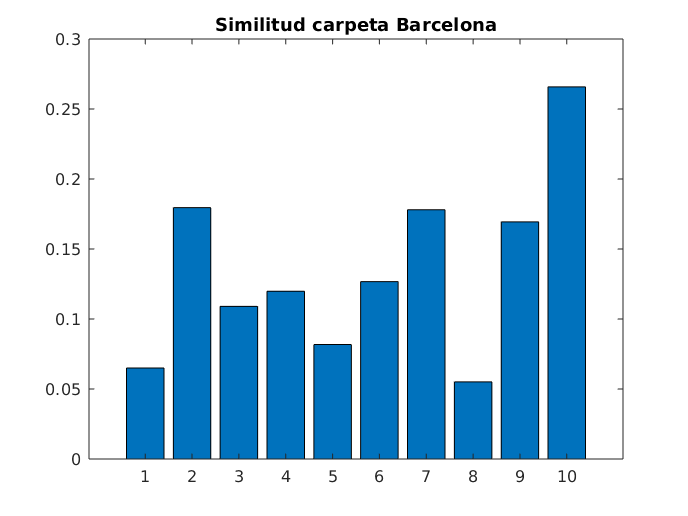

im = im2double(imnorm);
img = rgb2gray(im);
hist_im = imhist(img)./numel(img);
%[pattern_rows, pattern_cols, ~] = size(im);
pattern_rows = 100;
pattern_cols = 70;


y = zeros(1,10);

count = 0;

for i = 1:10
    chi = 100;
    
    novaim = imread(['barcelona/',num2str(i),'.jpg']);
    [im_rows, im_cols, ~] = size(novaim);
    newim = im2double(novaim);
    newimg = rgb2gray(newim);
    for row = floor(pattern_rows/2) +1:(im_rows-floor(pattern_rows/2))
        for col = floor(pattern_cols/2) +1:(im_cols-floor(pattern_cols/2))
		subim = newimg(row-floor(pattern_rows/2):row+floor(pattern_rows/2), col-floor(pattern_cols/2):col+floor(pattern_cols/2), :);
                hist_new = imhist(subim)./numel(subim);
                chi_tmp = sum(((hist_im - hist_new).^2) ./ (hist_im + hist_new));
                chi = min([chi, chi_tmp]);
                count = count +1;
        end
    end
    y(i) = chi;
    
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Barcelona');

y

y =     0.0650    0.1795    0.1090    0.1198    0.0818    0.1267    0.1781    0.0551    0.1694    0.2658


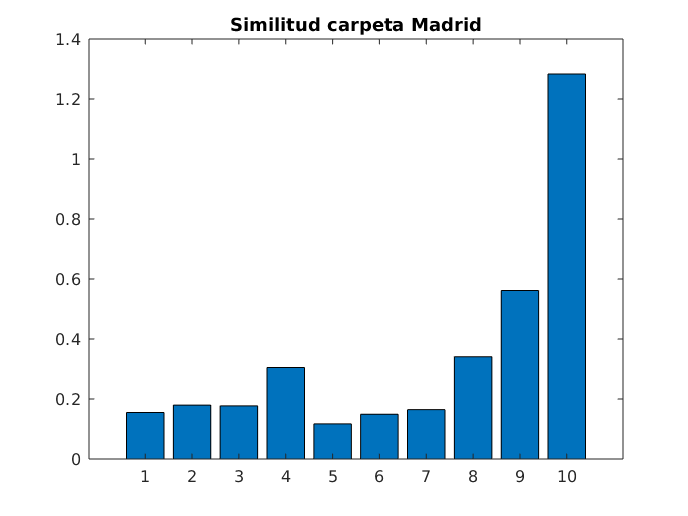

im = im2double(imnorm);
img = rgb2gray(im);
hist_im = imhist(img)./numel(img);
%[pattern_rows, pattern_cols, ~] = size(im);
pattern_rows = 100;
pattern_cols = 70;


y = zeros(1,10);

count = 0;

for i = 1:10
    chi = 100;
    
    novaim = imread(['madrid/',num2str(i),'.jpg']);
    [im_rows, im_cols, ~] = size(novaim);
    newim = im2double(novaim);
    newimg = rgb2gray(newim);
    for row = floor(pattern_rows/2) +1:(im_rows-floor(pattern_rows/2))
        for col = floor(pattern_cols/2) +1:(im_cols-floor(pattern_cols/2))
		subim = newimg(row-floor(pattern_rows/2):row+floor(pattern_rows/2), col-floor(pattern_cols/2):col+floor(pattern_cols/2), :);
                hist_new = imhist(subim)./numel(subim);
                chi_tmp = sum(((hist_im - hist_new).^2) ./ (hist_im + hist_new));
                chi = min([chi, chi_tmp]);
                count = count +1;
        end
    end
    y(i) = chi;
    
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Madrid');

y

y =     0.1548    0.1796    0.1769    0.3048    0.1171    0.1493    0.1647    0.3407    0.5616    1.2833


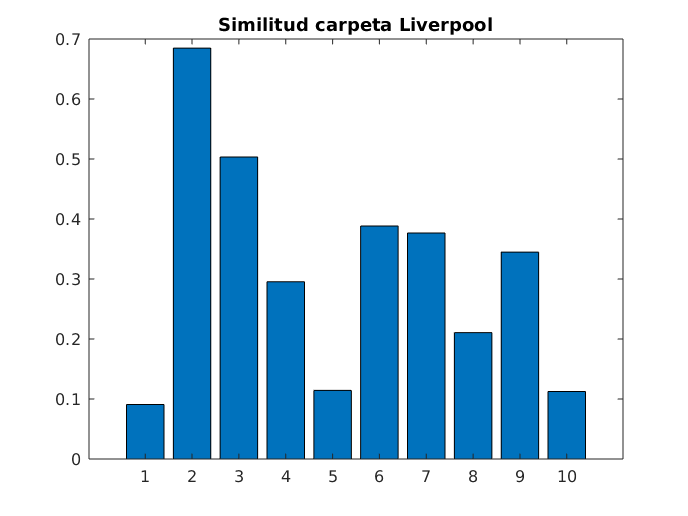

im = im2double(imnorm);
img = rgb2gray(im);
hist_im = imhist(img)./numel(img);
%[pattern_rows, pattern_cols, ~] = size(im);
pattern_rows = 100;
pattern_cols = 70;


y = zeros(1,10);

count = 0;

for i = 1:10
    chi = 100;
    
    novaim = imread(['liverpool/',num2str(i),'.jpg']);
    [im_rows, im_cols, ~] = size(novaim);
    newim = im2double(novaim);
    newimg = rgb2gray(newim);
    for row = floor(pattern_rows/2) +1:(im_rows-floor(pattern_rows/2))
        for col = floor(pattern_cols/2) +1:(im_cols-floor(pattern_cols/2))
		subim = newimg(row-floor(pattern_rows/2):row+floor(pattern_rows/2), col-floor(pattern_cols/2):col+floor(pattern_cols/2), :);
                hist_new = imhist(subim)./numel(subim);
                chi_tmp = sum(((hist_im - hist_new).^2) ./ (hist_im + hist_new));
                chi = min([chi, chi_tmp]);
                count = count +1;
        end
    end
    y(i) = chi;
    
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Liverpool');

y

y =     0.0908    0.6849    0.5034    0.2953    0.1143    0.3884    0.3766    0.2107    0.3448    0.1126


im = im2double(imnorm);
img = rgb2gray(im);
hist_im = imhist(img)./numel(img);

positive = imread('positiu.jpg');
%positive = NormalizeRB(positive);
positive = im2double(positive);
pos_pat = positive(85:170,150:210,:);
posg = rgb2gray(pos_pat);
hist_pos = imhist(posg)./numel(posg);


negative = imread('negatiu.jpg');
negatove = im2double(negative);
%negative = NormalizeRB(negative);
neg_pat = negative(110:210, 80:180,:);
negg = rgb2gray(neg_pat);
hist_neg = imhist(negg)./numel(negg);




chi_pos = 0.4951

chi_neg = 0.5986